clc;
clear;
close all;

T0 = 90;
Ta = 20;
T = 20;
k = 0.25;

Ns = [3, 5, 10, 20];

for j = 1:4
    [t, SOL] = IEMsolver(T0, Ta, T, k, Ns(j));
    plot(t, SOL);
    hold on;
end

     3

   37.3343   34.0152   25.8984

     5

    9.2484    8.0265    5.2649    3.0929    1.7158

    10

  Columns 1 through 8

    1.2929    1.5922    1.4707    1.2077    0.9298    0.6872    0.4939    0.3477

  Columns 9 through 10

    0.2410    0.1650

    20

  Columns 1 through 8

    0.1714    0.2675    0.3129    0.3255    0.3173    0.2970    0.2703    0.2410

  Columns 9 through 16

    0.2115    0.1833    0.1573    0.1338    0.1131    0.0950    0.0794    0.0661

  Columns 17 through 20

    0.0547    0.0452    0.0372    0.0306



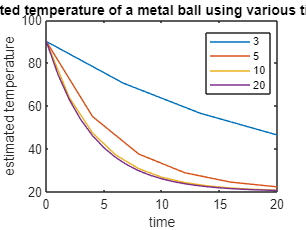


legend(string(Ns), location="best");
xlabel("time");
ylabel("estimated temperature");
title("estimated temperature of a metal ball using various time steps")

function [t, SOL] = IEMsolver(T0, Ta, T, k, N)
    dt = T/N;
    t = 0:dt:T;
    SOL = nan(1, length(t));
    SOL(1) = T0;

    for i = 2:length(t)
        zn = SOL(i-1);
        SL = -1*k*(zn - Ta);
        SR = -1*k*((zn + dt*SL) - Ta);
        SOL(i) = zn + dt/2*(SL+SR);
        true = 70*exp(-0.25*t(i))+20;
        err(i-1) = abs(SOL(i) - true);
    end

    disp(N);
    disp(err);
end

Using a time step of 20, the errors are below 1, making it a very resonable estimate.